%% =========================================================
%  ANÁLISIS BIOMECÁNICO DE SENTADILLA
%  Experto (P1) vs Novato (P2)
%  Flujo: Cargar → Segmentar → Normalizar → Estadística → Figuras
% =========================================================
clear; clc; close all;

% =========================================================
%  ► ZONA DE CONFIGURACIÓN — MODIFICAR AQUÍ
% =========================================================

% Nombres de los participantes (para etiquetas y leyendas)
NOMBRES = {"Novato", "Experto"};

% Rango de archivos CSV de cada participante dentro de files
% files = todos los CSV en la carpeta. Ajusta los índices según tu orden.
%   Ejemplo: si tienes 10 archivos, P1 = 1:5 y P2 = 6:10
IDX_P1 = 1:5;   % ← índices de archivos que pertenecen al P1
IDX_P2 = 6:10;  % ← índices de archivos que pertenecen al P2

% Qué series de cada participante analizar (índice dentro de sus 5 series)
% ► Series a analizar por participante (pueden ser distintas)
SERIES_P1 = [2 4 5];   % ← Experto
SERIES_P2 = [2 3 5];   % ← Novato

% Parámetros de detección de picos (findpeaks)
% Ajusta si la segmentación falla para algún ángulo
PICO_CADERA_MIN_DIST  = 50;
PICO_CADERA_MIN_PROM  = 10;
PICO_RODILLA_MIN_DIST = 100;
PICO_RODILLA_MIN_PROM = 8;
PICO_TRONCO_MIN_DIST  = 100;
PICO_TRONCO_MIN_PROM  = 20;

% Carpeta con los CSVs
CARPETA = 'angulos_recortados\';

% =========================================================
%  ETAPA 1 — CARGAR TODOS LOS CSV
% =========================================================
files = dir([CARPETA '*.csv']);

for k = 1:length(files)
    T = readtable([CARPETA files(k).name]);

    t      = T.Time;

    % ── Ángulo de CADERA ──────────────────────────────────
    theta_C = calcAngles(...
        T.Angle1_o_0_X, T.Angle1_o_0_Y, ...
        T.Angle1_a_0_X, T.Angle1_a_0_Y, ...
        T.Angle1_b_0_X, T.Angle1_b_0_Y);

    % ── Ángulo de RODILLA ─────────────────────────────────
    theta_R = calcAngles(...
        T.Angle2_o_0_X, T.Angle2_o_0_Y, ...
        T.Angle2_a_0_X, T.Angle2_a_0_Y, ...
        T.Angle2_b_0_X, T.Angle2_b_0_Y);

    % ── Ángulo de TRONCO ──────────────────────────────────
    % ► Si tienes columnas propias para el tronco, cámbialas aquí
    theta_T = calcAnglesT(...
        T.Angle1_o_0_X, T.Angle1_o_0_Y, ...
        T.Angle1_b_0_X, T.Angle1_b_0_Y);

    % Corrección de convención de signo
    theta_R = 180 - theta_R;
    theta_T = 180 - theta_T;

    % =========================================================
    %  ETAPA 2 — SEPARAR LAS 3 REPETICIONES AUTOMÁTICAMENTE
    % =========================================================

    % Detectar picos de CADERA para definir cortes generales
    [~, locs_C] = findpeaks(theta_C, ...
        'MinPeakDistance', PICO_CADERA_MIN_DIST, ...
        'MinPeakProminence', PICO_CADERA_MIN_PROM);

    cortes = [1, locs_C', length(theta_C)];

    % Inicializar celdas de segmentos
    segC = {}; segR = {}; segT = {}; segT_tiempo = {};

    for i = 1:length(cortes)-1
        ini = cortes(i);
        fin = cortes(i+1);

        segC{i}        = theta_C(ini:fin);
        segR{i}        = theta_R(ini:fin);
        segT{i}        = theta_T(ini:fin);
        segT_tiempo{i} = t(ini:fin);

        % PMF de cada segmento
        [~, idxC] = min(segC{i});          % cadera: mínimo en PMF
        [~, idxR] = max(segR{i});          % rodilla: máximo en PMF
        [~, idxT] = min(segT{i});          % tronco:  mínimo en PMF

        locsC{i} = idxC;
        locsR{i} = idxR;
        locsT{i} = idxT;
    end

    % Guardar en estructura data
    data(k).archivo      = files(k).name;
    data(k).t            = t;
    data(k).cadera       = theta_C;
    data(k).rodilla      = theta_R;
    data(k).tronco       = theta_T;
    data(k).segmentosC   = segC;
    data(k).segmentosR   = segR;
    data(k).segmentosT   = segT;
    data(k).segTiempo    = segT_tiempo;
    data(k).locsC        = locsC;
    data(k).locsR        = locsR;
    data(k).locsT        = locsT;
end

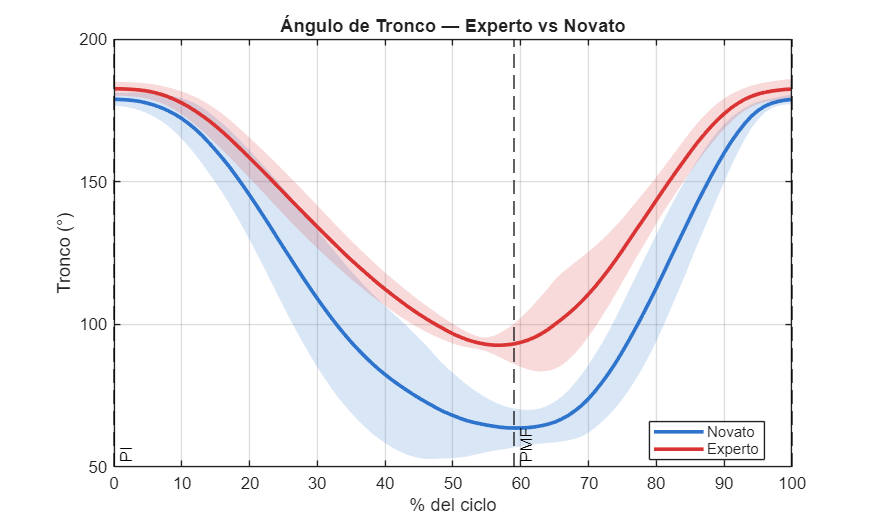

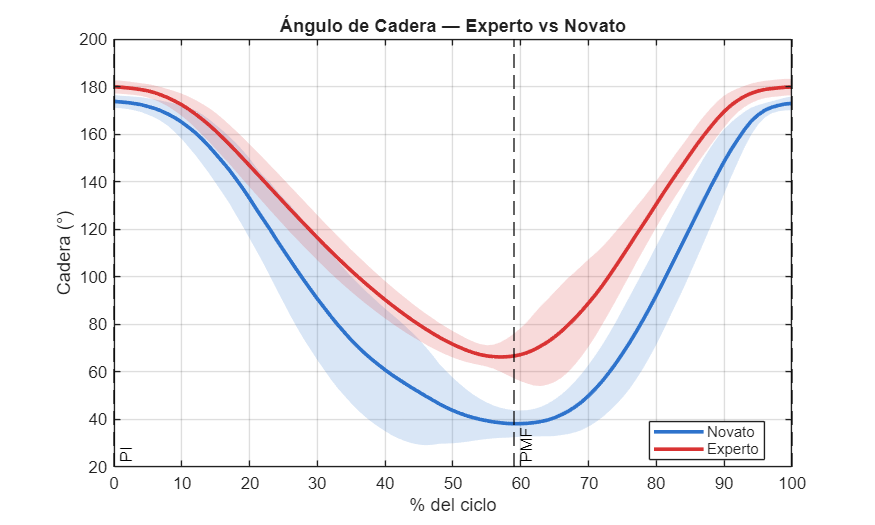

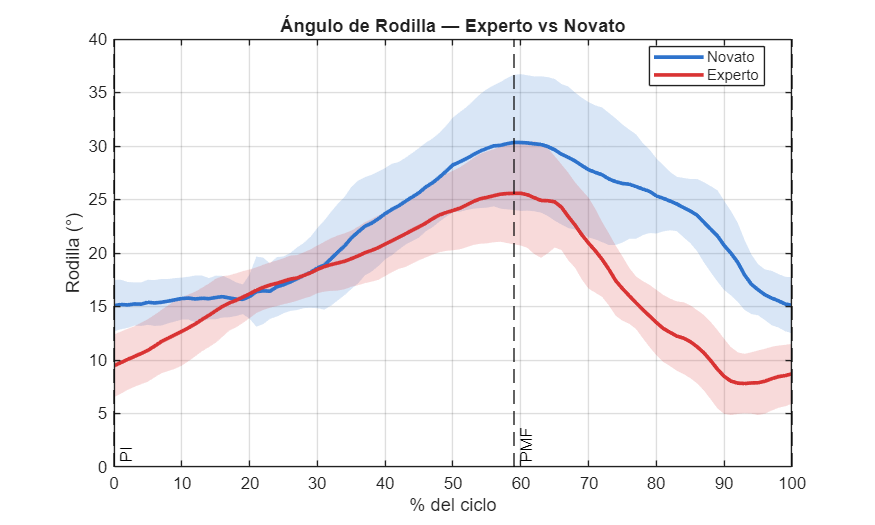


% =========================================================
%  SEPARAR PARTICIPANTES
% =========================================================
Participante(1).nombre = NOMBRES{1};
Participante(1).series = data(IDX_P1);

Participante(2).nombre = NOMBRES{2};
Participante(2).series = data(IDX_P2);

Participante(1).seriesAnalizar = SERIES_P1;
Participante(2).seriesAnalizar = SERIES_P2;

% =========================================================
%  ETAPAS 3-8 — NORMALIZAR, EXTRAER VARIABLES, ESTADÍSTICA
% =========================================================
N_NORM = 101;   % puntos de normalización (0 a 100%)
xNorm  = linspace(0, 100, N_NORM);

angulos_nombres = {'tronco', 'cadera', 'rodilla'};

for p = 1:2

    % Matrices para acumular las 9 repeticiones normalizadas (3 series × 3 reps)
    matC_norm = [];   % 101 × 9
    matR_norm = [];
    matT_norm = [];

    % Vectores de variables por repetición
    PI_C = []; PMF_C = []; PF_C = [];
    PI_R = []; PMF_R = []; PF_R = [];
    PI_T = []; PMF_T = []; PF_T = [];
    ROM_C = []; ROM_R = []; ROM_T = [];
    t_exc = []; t_con = []; t_tot = [];

    seriesP = Participante(p).seriesAnalizar;
    for sIdx = 1:length(seriesP)
        s = seriesP(sIdx);
        serie = Participante(p).series(s);

        for r = 1:length(serie.segmentosC)

            segC = serie.segmentosC{r};
            segR = serie.segmentosR{r};
            segT = serie.segmentosT{r};
            tSeg = serie.segTiempo{r};

            xOrig = linspace(0, 100, length(segC));

            % ── ETAPA 3: Normalizar a 101 puntos ──────────
            matC_norm(:, end+1) = interp1(xOrig, segC, xNorm, 'spline')';
            matR_norm(:, end+1) = interp1(xOrig, segR, xNorm, 'spline')';
            matT_norm(:, end+1) = interp1(xOrig, segT, xNorm, 'spline')';

            % ── ETAPA 6: Instantes clave ───────────────────
            idxPMF_C = serie.locsC{r};
            idxPMF_R = serie.locsR{r};
            idxPMF_T = serie.locsT{r};

            PI_C(end+1)  = segC(1);
            PMF_C(end+1) = segC(idxPMF_C);
            PF_C(end+1)  = segC(end);

            PI_R(end+1)  = segR(1);
            PMF_R(end+1) = segR(idxPMF_R);
            PF_R(end+1)  = segR(end);

            PI_T(end+1)  = segT(1);
            PMF_T(end+1) = segT(idxPMF_T);
            PF_T(end+1)  = segT(end);

            % ── ETAPA 7: ROM ───────────────────────────────
            ROM_C(end+1) = calcROM(segC);
            ROM_R(end+1) = calcROM(segR);
            ROM_T(end+1) = calcROM(segT);

            % ── ETAPA 8: Tiempos y ratio E/C ──────────────
            % Se usa el PMF de cadera como punto de máxima flexión
            [te, tc] = calcPhases(tSeg, idxPMF_C);
            t_exc(end+1) = te;
            t_con(end+1) = tc;
            t_tot(end+1) = te + tc;
        end
    end

    % Guardar matrices normalizadas
    Participante(p).matC_norm = matC_norm;
    Participante(p).matR_norm = matR_norm;
    Participante(p).matT_norm = matT_norm;

    % ── ETAPA 5: Curva promedio ± DE ──────────────────────
    Participante(p).meanC = mean(matC_norm, 2);
    Participante(p).stdC  = std(matC_norm, 0, 2);
    Participante(p).meanR = mean(matR_norm, 2);
    Participante(p).stdR  = std(matR_norm, 0, 2);
    Participante(p).meanT = mean(matT_norm, 2);
    Participante(p).stdT  = std(matT_norm, 0, 2);

    % ── Estadística de instantes clave ────────────────────
    Participante(p).stats.PI_C  = calcStats(PI_C);
    Participante(p).stats.PMF_C = calcStats(PMF_C);
    Participante(p).stats.PF_C  = calcStats(PF_C);

    Participante(p).stats.PI_R  = calcStats(PI_R);
    Participante(p).stats.PMF_R = calcStats(PMF_R);
    Participante(p).stats.PF_R  = calcStats(PF_R);

    Participante(p).stats.PI_T  = calcStats(PI_T);
    Participante(p).stats.PMF_T = calcStats(PMF_T);
    Participante(p).stats.PF_T  = calcStats(PF_T);

    Participante(p).stats.ROM_C = calcStats(ROM_C);
    Participante(p).stats.ROM_R = calcStats(ROM_R);
    Participante(p).stats.ROM_T = calcStats(ROM_T);

    Participante(p).stats.t_exc = calcStats(t_exc);
    Participante(p).stats.t_con = calcStats(t_con);
    Participante(p).stats.t_tot = calcStats(t_tot);
    Participante(p).stats.ratio = calcStats(t_exc ./ t_con);
end

% =========================================================
%  ETAPA 9 — GRÁFICAS
% =========================================================

colExp  = [0.18 0.45 0.80];   % azul  — Experto
colNov  = [0.85 0.20 0.20];   % rojo  — Novato
alpBand = 0.18;                % transparencia de la banda ± DE

nombreAngulos = {'Tronco (°)', 'Cadera (°)', 'Rodilla (°)'};
meanExp = {Participante(1).meanT, Participante(1).meanC, Participante(1).meanR};
stdExp  = {Participante(1).stdT,  Participante(1).stdC,  Participante(1).stdR};
meanNov = {Participante(2).meanT, Participante(2).meanC, Participante(2).meanR};
stdNov  = {Participante(2).stdT,  Participante(2).stdC,  Participante(2).stdR};

% ── GRÁFICAS 1-3: Una por ángulo (Tronco, Cadera, Rodilla) ──────────────
for a = 1:3

    mE = meanExp{a};  sE = stdExp{a};
    mN = meanNov{a};  sN = stdNov{a};

    % Buscar posición aproximada del PMF en la curva media del experto
    if a == 3   % rodilla: PMF = máximo
        [~, idxPMF] = max(mE);
    else        % tronco / cadera: PMF = mínimo
        [~, idxPMF] = min(mE);
    end
    pctPMF = xNorm(idxPMF);

    figure('Position', [100, 100, 700, 420]);

    % Banda Experto
    fill([xNorm, fliplr(xNorm)], ...
         [(mE + sE)', fliplr((mE - sE)')], ...
         colExp, 'FaceAlpha', alpBand, 'EdgeColor', 'none'); hold on;

    % Banda Novato
    fill([xNorm, fliplr(xNorm)], ...
         [(mN + sN)', fliplr((mN - sN)')], ...
         colNov, 'FaceAlpha', alpBand, 'EdgeColor', 'none');

    % Curvas medias
    hE = plot(xNorm, mE, '-',  'Color', colExp, 'LineWidth', 2.2);
    hN = plot(xNorm, mN, '-',  'Color', colNov, 'LineWidth', 2.2);

    % Líneas verticales PI, PMF, PF
    yLim = ylim;
    xline(0,      '--k', 'PI',  'LabelVerticalAlignment','bottom', 'LineWidth', 1);
    xline(pctPMF, '--k', 'PMF', 'LabelVerticalAlignment','bottom', 'LineWidth', 1);
    xline(100,    '--k', 'PF',  'LabelVerticalAlignment','bottom', 'LineWidth', 1);

    xlabel('% del ciclo'); ylabel(nombreAngulos{a});
    title(['Ángulo de ' strrep(nombreAngulos{a},' (°)','') ' — Experto vs Novato']);
    legend([hE hN], {Participante(1).nombre, Participante(2).nombre}, 'Location','best');
    grid on; box on;

    % Exportar
    exportgraphics(gcf, sprintf('figura_%d_%s.png', a, lower(strrep(nombreAngulos{a},' (°)',''))),...
        'Resolution', 300);
end

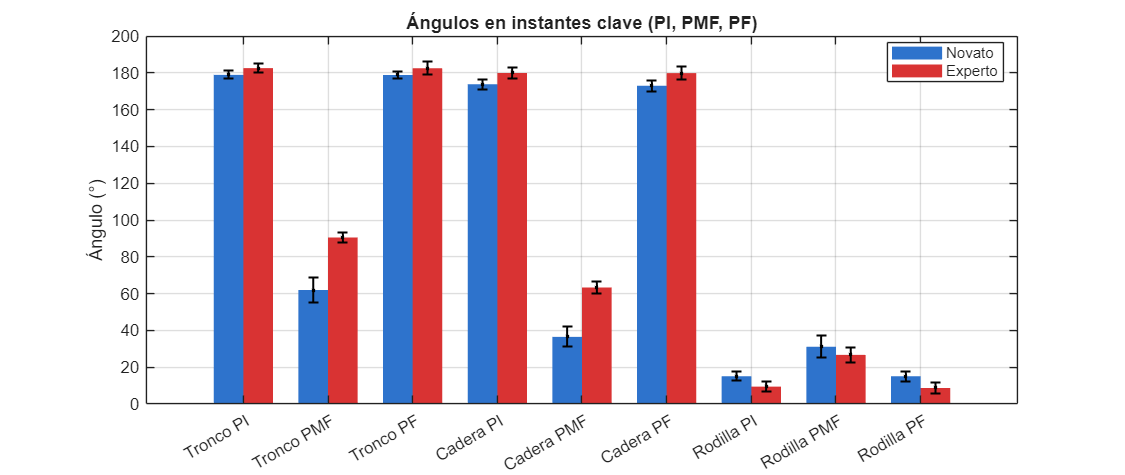


% ── GRÁFICA 4: Barras en instantes clave (PI, PMF, PF) ──────────────────
figure('Position', [100, 100, 900, 380]);

etqAngulos = {'Tronco','Cadera','Rodilla'};
instantes  = {'PI','PMF','PF'};
camposP = {{'PI_T','PMF_T','PF_T'}, {'PI_C','PMF_C','PF_C'}, {'PI_R','PMF_R','PF_R'}};

nGrupos = 9;   % 3 ángulos × 3 instantes
valsExp = zeros(1, nGrupos);
valsNov = zeros(1, nGrupos);
errsExp = zeros(1, nGrupos);
errsNov = zeros(1, nGrupos);
etqX    = {};

g = 0;
for a = 1:3
    for i = 1:3
        g = g + 1;
        campo = camposP{a}{i};
        valsExp(g) = Participante(1).stats.(campo).mean;
        valsNov(g) = Participante(2).stats.(campo).mean;
        errsExp(g) = Participante(1).stats.(campo).std;
        errsNov(g) = Participante(2).stats.(campo).std;
        etqX{g} = [etqAngulos{a} ' ' instantes{i}];
    end
end

xPos = 1:nGrupos;
bar_w = 0.35;
bE = bar(xPos - bar_w/2, valsExp, bar_w, 'FaceColor', colExp, 'EdgeColor','none'); hold on;
bN = bar(xPos + bar_w/2, valsNov, bar_w, 'FaceColor', colNov, 'EdgeColor','none');
errorbar(xPos - bar_w/2, valsExp, errsExp, 'k.', 'LineWidth', 1.2);
errorbar(xPos + bar_w/2, valsNov, errsNov, 'k.', 'LineWidth', 1.2);

set(gca, 'XTick', xPos, 'XTickLabel', etqX, 'XTickLabelRotation', 30);
ylabel('Ángulo (°)');
title('Ángulos en instantes clave (PI, PMF, PF)');
legend([bE bN], {Participante(1).nombre, Participante(2).nombre}, 'Location','best');
grid on; box on;
exportgraphics(gcf, 'figura_4_instantes_clave.png', 'Resolution', 300);

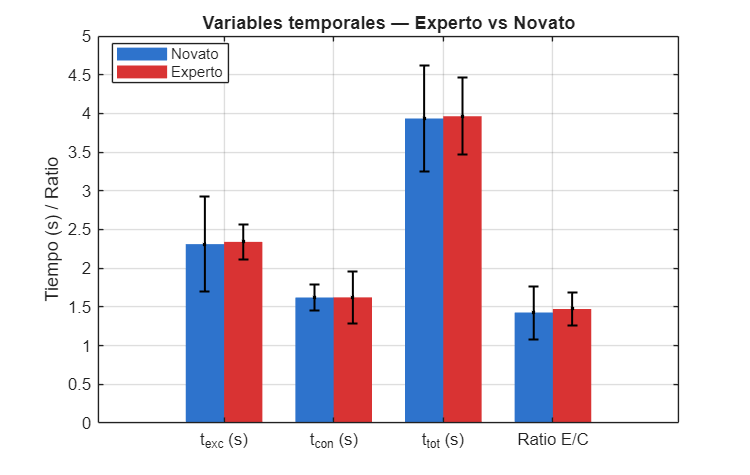


% ── GRÁFICA 5: Variables temporales ─────────────────────────────────────
figure('Position', [100, 100, 600, 380]);

camposT = {'t_exc','t_con','t_tot','ratio'};
etqT    = {'t_{exc} (s)','t_{con} (s)','t_{tot} (s)','Ratio E/C'};

vE2 = zeros(1,4); vN2 = zeros(1,4);
eE2 = zeros(1,4); eN2 = zeros(1,4);
for i = 1:4
    vE2(i) = Participante(1).stats.(camposT{i}).mean;
    vN2(i) = Participante(2).stats.(camposT{i}).mean;
    eE2(i) = Participante(1).stats.(camposT{i}).std;
    eN2(i) = Participante(2).stats.(camposT{i}).std;
end

xT = 1:4;
bE2 = bar(xT - bar_w/2, vE2, bar_w, 'FaceColor', colExp, 'EdgeColor','none'); hold on;
bN2 = bar(xT + bar_w/2, vN2, bar_w, 'FaceColor', colNov, 'EdgeColor','none');
errorbar(xT - bar_w/2, vE2, eE2, 'k.', 'LineWidth', 1.2);
errorbar(xT + bar_w/2, vN2, eN2, 'k.', 'LineWidth', 1.2);

set(gca, 'XTick', xT, 'XTickLabel', etqT);
ylabel('Tiempo (s) / Ratio');
title('Variables temporales — Experto vs Novato');
legend([bE2 bN2], {Participante(1).nombre, Participante(2).nombre}, 'Location','best');
grid on; box on;
exportgraphics(gcf, 'figura_5_tiempos.png', 'Resolution', 300);


% =========================================================
%  ETAPA 10 — TABLAS PARA EL PAPER
% =========================================================

fprintf('\n══════════════════════════════════════════════════════════════════\n');


══════════════════════════════════════════════════════════════════


fprintf('TABLA II — Ángulos en instantes clave + ROM\n');

TABLA II — Ángulos en instantes clave + ROM


fprintf('%-14s  %-18s  %-18s  %-8s\n', 'Variable', ...
    [Participante(1).nombre ' (x̄ ± DE)'], ...
    [Participante(2).nombre ' (x̄ ± DE)'], 'Δ');

Variable        Novato               (x̄ ± DE)          Experto 
 (x̄ ± DE)      Δ                   

fprintf('──────────────────────────────────────────────────────────────────\n');

──────────────────────────────────────────────────────────────────



camposTabII = {...
    'PI_T',  'θ_T  PI'; ...
    'PMF_T', 'θ_T  PMF'; ...
    'PF_T',  'θ_T  PF'; ...
    'ROM_T', 'ROM θ_T'; ...
    'PI_C',  'θ_C  PI'; ...
    'PMF_C', 'θ_C  PMF'; ...
    'PF_C',  'θ_C  PF'; ...
    'ROM_C', 'ROM θ_C'; ...
    'PI_R',  'θ_R  PI'; ...
    'PMF_R', 'θ_R  PMF'; ...
    'PF_R',  'θ_R  PF'; ...
    'ROM_R', 'ROM θ_R'};

for i = 1:size(camposTabII,1)
    campo  = camposTabII{i,1};
    etiq   = camposTabII{i,2};
    m1 = Participante(1).stats.(campo).mean;
    s1 = Participante(1).stats.(campo).std;
    m2 = Participante(2).stats.(campo).mean;
    s2 = Participante(2).stats.(campo).std;
    delta = abs(m1 - m2);
    fprintf('%-14s  %7.2f ± %6.2f    %7.2f ± %6.2f    %6.2f\n', ...
        etiq, m1, s1, m2, s2, delta);
end

θ_T  PI          178.86 ±   2.22     182.55 ±   2.44      3.69
θ_T  PMF          61.95 ±   6.79      90.48 ±   2.48     28.53
θ_T  PF          178.83 ±   1.67     182.45 ±   3.47      3.61
ROM θ_T          117.99 ±   6.58      92.96 ±   4.30     25.03
θ_C  PI          173.77 ±   2.68     179.89 ±   2.77      6.12
θ_C  PMF          36.46 ±   5.43      63.31 ±   3.49     26.84
θ_C  PF          172.94 ±   2.85     179.80 ±   3.43      6.86
ROM θ_C          137.79 ±   6.20     117.68 ±   6.15     20.11
θ_R  PI           15.08 ±   2.40       9.46 ±   2.93      5.63
θ_R  PMF          31.11 ±   6.06      26.72 ±   3.97      4.39
θ_R  PF           15.12 ±   2.63       8.71 ±   2.80      6.40
ROM θ_R           17.71 ±   6.13      19.95 ±   4.29      2.24



fprintf('\n══════════════════════════════════════════════════════════════════\n');


══════════════════════════════════════════════════════════════════


fprintf('TABLA III — Variables temporales\n');

TABLA III — Variables temporales


fprintf('%-14s  %-18s  %-18s  %-8s\n', 'Variable', ...
    [Participante(1).nombre ' (x̄ ± DE)'], ...
    [Participante(2).nombre ' (x̄ ± DE)'], 'Δ');

Variable        Novato               (x̄ ± DE)          Experto 
 (x̄ ± DE)      Δ                   

fprintf('──────────────────────────────────────────────────────────────────\n');

──────────────────────────────────────────────────────────────────



camposTabIII = {...
    't_exc', 't_{exc} (s)'; ...
    't_con', 't_{con} (s)'; ...
    't_tot', 't_{tot} (s)'; ...
    'ratio', 'Ratio E/C'};

for i = 1:size(camposTabIII,1)
    campo = camposTabIII{i,1};
    etiq  = camposTabIII{i,2};
    m1 = Participante(1).stats.(campo).mean;
    s1 = Participante(1).stats.(campo).std;
    m2 = Participante(2).stats.(campo).mean;
    s2 = Participante(2).stats.(campo).std;
    delta = abs(m1 - m2);
    fprintf('%-14s  %7.2f ± %6.2f    %7.2f ± %6.2f    %6.2f\n', ...
        etiq, m1, s1, m2, s2, delta);
end

t_{exc} (s)        2.31 ±   0.61       2.34 ±   0.22      0.03
t_{con} (s)        1.62 ±   0.17       1.62 ±   0.34      0.00
t_{tot} (s)        3.93 ±   0.69       3.96 ±   0.50      0.03
Ratio E/C          1.43 ±   0.34       1.47 ±   0.21      0.05


fprintf('══════════════════════════════════════════════════════════════════\n\n');

══════════════════════════════════════════════════════════════════




% =========================================================
%  FUNCIONES AUXILIARES
% =========================================================

function theta = calcAngles(Ox, Oy, Ax, Ay, Bx, By)
    OAx = Ax - Ox;  OAy = Ay - Oy;
    OBx = Bx - Ox;  OBy = By - Oy;
    dot   = OAx.*OBx + OAy.*OBy;
    cross = OAx.*OBy - OAy.*OBx;
    theta = atan2d(cross, dot);
    theta(theta < 0) = theta(theta < 0) + 360;
end

function theta = calcAnglesT(Ox, Oy, Ax, Ay)
    % ► Si el tronco usa puntos distintos a los de la cadera, cámbialos aquí
    OAx = Ax - Ox;
    OAy = Ay - Oy;
    theta = atan2d(OAx, OAy);
end

function rom = calcROM(theta)
    rom = max(theta) - min(theta);
end

function dur = calcDuration(t)
    dur = t(end) - t(1);
end

function [tEcc, tCon] = calcPhases(t, idxPMF)
    tEcc = t(idxPMF) - t(1);
    tCon = t(end)    - t(idxPMF);
end

function S = calcStats(x)
    S.data = x;
    S.mean = mean(x);
    S.std  = std(x);
    S.min  = min(x);
    S.max  = max(x);
    S.rng  = max(x) - min(x);
end